MIFB


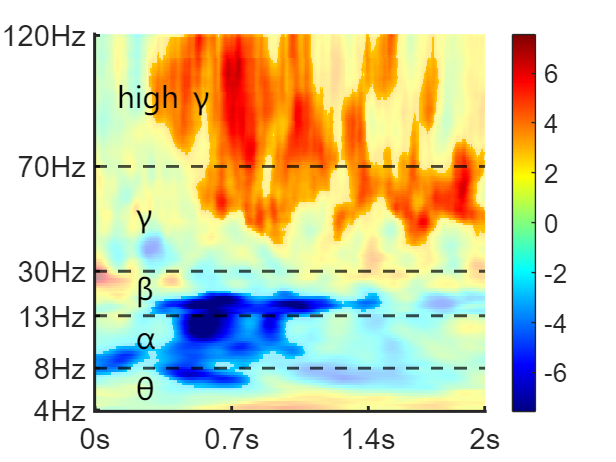

SCC


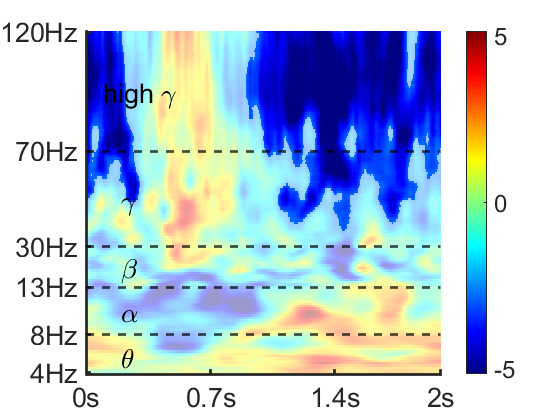

TempB


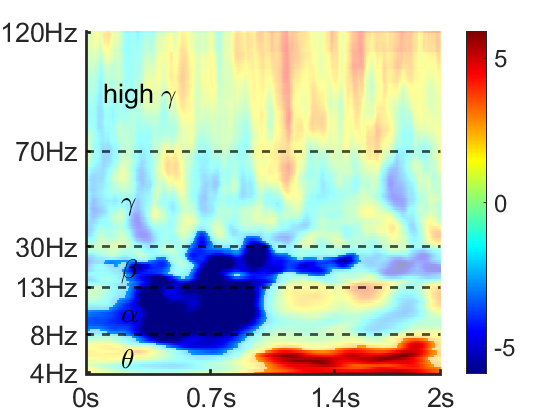

clc; clear; close all;
cd('Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\fig2_whiteMatter_timeFrequency');
AtlasLabels = {'MIFB', 'SCC', 'TempB'};
fsample = 250;
foi1 = 4:0.25:13; foi2 = 13:1:120; foi = unique([foi1, foi2]);
for nAL = 1:length(AtlasLabels)
    load(fullfile('s5_TFRloadingEffect_allRightTrials', ['LoadingEffect_clusterPermTest_0b2b_', AtlasLabels{nAL}, '_001.mat']));
    t = t_orig;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % significant postive cluster
    posClusterIds = clust_info.pos_clust_ids;
    posClusterP = clust_info.pos_clust_pval;
    sigIds = find(posClusterP<0.01);
    posClusterMask = zeros(size(posClusterIds));
    for n = 1:length(sigIds)
        posClusterMask(posClusterIds==sigIds(n)) = 1;
    end
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % significant negative cluster
    negClusterIds = clust_info.neg_clust_ids;
    negClusterP = clust_info.neg_clust_pval;
    sigIds = find(negClusterP<0.01);
    negClusterMask = zeros(size(negClusterIds));
    for n = 1:length(sigIds)
        negClusterMask(negClusterIds==sigIds(n)) = 1;
    end
    ClusterMask = posClusterMask + negClusterMask;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    disp(AtlasLabels{nAL});
    figure;
    lims = min(abs(min(t(:))), abs(max(t(:))));
    clims = [-lims, lims];
    imagesc(t, clims);
    axis xy; colorbar; colormap jet; hold on;
    alphaData = ones(size(t));
    alphaData(ClusterMask == 0) = 0.4;
    ax = gca();
    set(ax.Children, 'AlphaData', alphaData);
    set(ax, 'ALim', [0 1]);
    yline([17, 37, 54, 94], 'LineWidth', 2, 'LineStyle', '--', 'Color', [0 0 0]);
    xticks([1:0.7*fsample:2*fsample, 2*fsample]);
    xticklabels({'0s', '0.7s', '1.4s', '2s'});
    yticks([1, 17, 37, 54, 94, 144]);
    yticklabels({'4Hz', '8Hz', '13Hz', '30Hz', '70Hz', '120Hz'});
    text([0.2*fsample, 0.2*fsample, 0.2*fsample, 0.2*fsample, 0.1*250], [7.5, 27, 45.5, 74, 119], ...
        {'\theta', '\alpha', '\beta', '\gamma', 'high \gamma'}, 'FontName', 'Bold', 'FontSize', 20);
    set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 20, 'LineWidth', 2); 
    hold off;
end